# ADACS Homework 3

By: $\underline{Dillon \ Allen}$

## Scenario

The equations governing a rigid body is


$$\frac{d}{dt} H = 0 \Longrightarrow \frac{d}{dt} \left( \left[I \right] \right) \omega = 0$$



$$\frac{d}{dt} \left( \left[ I \right] \omega \right) = \left[ I \right] \dot{\omega} + \omega \times \left( \left[ I \right] \omega \right)$$



$$\dot{\omega} = - \left[ I \right] ^{-1} \left( \omega \times \left( \left[ I \right] \omega \right)$$


## Problem 1

Expand the equations and write in the form


$$\frac{d}{dt} \omega = f \left(\omega, t\right)$$


Solution:


$$\left[I\right] \omega = \pmatrix{I_{x} & 0 & 0 \cr 0 & I_{y} & 0 \cr 0 & 0 & I_{z}} \pmatrix{\omega_{x} \cr \omega_{y} \cr \omega_{z}} = \pmatrix{I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z}$$



$$\omega \times \left[I\right] \omega = \pmatrix{\omega_x \cr \omega_y \cr \omega_z} \times \pmatrix{ I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z} = \pmatrix{\omega_y \omega_z \left(I_z - I_y\right) \cr \omega_x \omega_z \left( I_x - I_z \right) \cr \omega_x \omega_y \left( I_y - I_x\right)}$$



$$\left[ I \right]^{-1} = \pmatrix{\frac{1}{I_x} & 0 & 0 \cr 0 & \frac{1}{I_y} & 0 \cr 0 & 0 & \frac{1}{I_z}}$$



$$\frac{d}{dt} \omega = - \left[ I \right]^{-1} \left( \omega \times \left[ I \right] \omega \right)$$



$$\frac{d}{dt} \omega = \pmatrix{-I_x^{-1} & 0 & 0 \cr 0 & -I_y^{-1} & 0 \cr 0 & 0 & -I_z^{-1}} \pmatrix{\omega_y \omega_z \left(I_z - I_y \right) \cr \omega_x \omega_z \left(I_x - I_z\right) \cr \omega_x \omega_y \left(I_y - I_x\right)} = \pmatrix{\omega_y \omega_z \left(\frac{I_y - I_z}{I_x}\right) \cr \omega_x \omega_z \left( \frac{I_z - I_x}{I_y} \right) \cr \omega_x \omega_y \left( \frac{I_x - I_y}{I_z}\right)}$$


Thus, the three differential equations are


$$\dot{\omega}_{x} = \omega_y \omega_z \left( \frac{I_y - I_z}{I_x} \right)$$



$$\dot{\omega}_{y} = \omega_x \omega_z \left(\frac{I_z - I_x}{I_y}\right)$$



$$\dot{\omega}_{z} = \omega_x \omega_y \left( \frac{I_x - I_y}{I_z} \right)$$


## Problem 2

Write the expression for the magnitude of the total momentum (h) and the rotational kinetic energy (T)

Solution:

The equation for the total momentum is


$$\textbf{h} = \left[ I \right] \omega$$



$$\textbf{h} = \pmatrix{I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z}$$



$$|\! | h |\!| = \sqrt{I_x^2 \omega_x^2 + I_y^2 \omega_y^2 + I_z^2 \omega_z^2}$$


The equation for the rotational Kinetic Energy is 


$$T_{\text{rot}} = \frac{1}{2} \omega^{T} \left[ I \right] \omega$$



$$T_{\text{rot}} = \frac{1}{2} \pmatrix{\omega_x & \omega_y & \omega_z} \pmatrix{I_x \omega_x \cr I_y \omega_y \cr I_z \omega_z} = \frac{1}{2} \left( I_x \omega_x^2 + I_y \omega_y^2 + I_z \omega_z^2 \right)$$


## Problem 3 (Function at bottom)

Run the problem for the following conditions

- [I] = diag([100,200,300])

- $\omega_x = 0$, $\omega_y = 1 \frac{\text{deg}}{\text{sec}}$, $\omega_z = 30\ \text{rpm}$

- time span of 20 seconds

And find the following:

- Plot the angular rates as a function of time

- Plot the total momentum and kinetic energy vs time

- Show the total momentum and kinetic energy are constant

- Show that the resulting motion is sinusoidal with period of about 4.24 seconds.

Solution:

% Initial Conditions
Imat1 = diag([100, 200, 300]);

w_initial1_x = 0;
w_initial1_y = 1 * (pi/180); % deg/s -> rad/s
w_initial1_z = 30 * (2*pi/60);  % rpm -> rad/s

w_initial1 = [w_initial1_x; w_initial1_y; w_initial1_z];

tspan1 = 0:20; % seconds

[w1, momenta_matrix1, totMomentum1, Trot1] = AngularRateODESolver(Imat1, w_initial1, tspan1)

w1 =          0    0.0175    3.1416
    0.0000   -0.0175    3.1416
   -0.0000    0.0175    3.1416
    0.0000   -0.0175    3.1416
   -0.0000    0.0175    3.1416
    0.0000   -0.0174    3.1416
   -0.0000    0.0174    3.1416
    0.0000   -0.0174    3.1416
   -0.0000    0.0174    3.1416
    0.0000   -0.0174    3.1416


momenta_matrix1 = 1×21 cell array
    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}


totMomentum1 = 1×21 cell array
    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}    {[942.4843]}


Trot1 = 1×21 cell array
    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}    {[1.4805e+03]}



% Peak Finding for Period
[~,locs] = findpeaks(w1(:,1),tspan1);
period = max(diff(locs))

period = 2

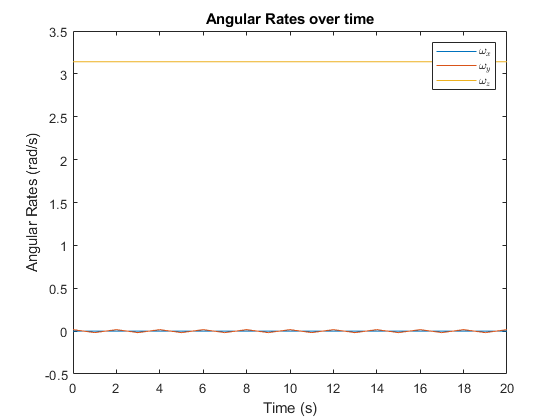

% Angular Rate Plot
figure(1)
plot(tspan1, w1(:,1));
hold on
plot(tspan1, w1(:,2));
plot(tspan1, w1(:,3));
hold off;
title("Angular Rates over time");
xlabel("Time (s)");
ylabel("Angular Rates (rad/s)");
legend("$\omega_x$", "$\omega_y$", "$\omega_z$", 'Interpreter',"latex")

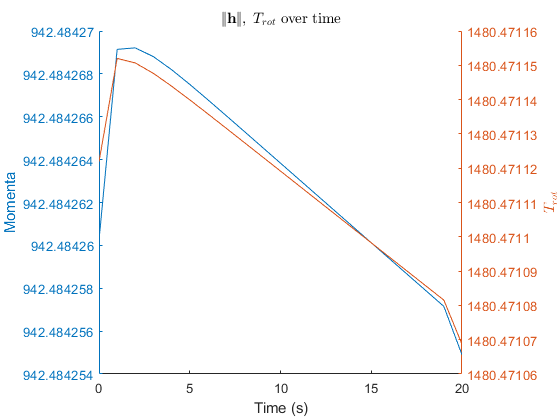

% Total Momentum and Kinetic Energy Plots

figure(2)
hold on
yyaxis left
plot(tspan1,cell2mat(totMomentum1))
ylabel("Momenta")
xlabel("Time (s)");
yyaxis right
plot(tspan1, cell2mat(Trot1));
ylabel("$T_{rot}$", "Interpreter","latex")
hold off;
title("$|\!| \textbf{h} |\!|,\ T_{rot} $ over time","Interpreter","latex")

## Problem 4

With the same body, re-run the simulation with new parameters:

- [I] = diag([100, 200, 300]);

- $\omega_x = 1 \frac{\text{deg}}{\text{sec}}$, $\omega_y = 30 \ \text{rpm}$, $\omega_z = 0$

- time span: 20 seconds

Solution:

% Initial Conditions

% Moment of Inertia Matrix
Imat2 = diag([100,200,300]);

% Initial Angular Rates
w_initial2_x = 1 * (pi/180); % deg/s -> rad/s
w_initial2_y = 30 * (2*pi/60); % rpm -> rad/s
w_initial2_z = 0;
w_initial2 = [w_initial2_x; w_initial2_y; w_initial2_z];

tspan2 = 0:20;

[w2, momenta_matrix2, totMomentum2, Trot2] = AngularRateODESolver(Imat2, w_initial2, tspan2)

w2 =     0.0175    3.1416         0
    0.0549    3.1412   -0.0301
    0.3277    3.1244   -0.1889
    1.8275    2.5582   -1.0550
    2.5436   -1.8252   -1.4685
    0.5234   -3.0834   -0.3020
    0.0875   -3.1258   -0.0495
    0.0196   -3.1269   -0.0051
    0.0349   -3.1268    0.0174
    0.1980   -3.1207    0.1139


momenta_matrix2 = 1×21 cell array
    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}    {3×1 double}


totMomentum2 = 1×21 cell array
    {[628.3210]}    {[628.3208]}    {[628.2916]}    {[628.7774]}    {[626.1351]}    {[625.4902]}    {[625.3914]}    {[625.3903]}    {[625.3903]}    {[625.3872]}    {[625.4765]}    {[625.1013]}    {[624.7783]}    {[624.6520]}    {[624.6447]}    {[624.6446]}    {[624.6418]}    {[624.6805]}    {[626.3599]}    {[621.4977]}    {[621.3500]}


Trot2 = 1×21 cell array
    {[986.9757]}    {[986.9752]}    {[986.8836]}    {[988.4103]}    {[980.1206]}    {[978.1026]}    {[977.7936]}    {[977.7902]}    {[977.7901]}    {[977.7806]}    {[978.0599]}    {[976.8866]}    {[975.8774]}    {[975.4831]}    {[975.4600]}    {[975.4597]}    {[975.4510]}    {[975.5721]}    {[980.8245]}    {[965.6562]}    {[965.1973]}


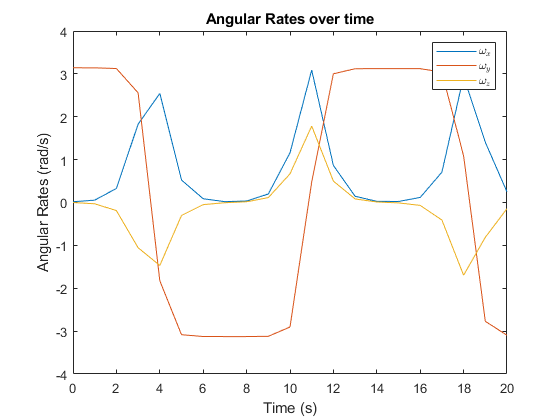

% Angular Rates Plot
figure(3)
plot(tspan2, w2(:,1));
hold on
plot(tspan2, w2(:,2));
plot(tspan2, w2(:,3));
hold off;
title("Angular Rates over time");
xlabel("Time (s)");
ylabel("Angular Rates (rad/s)");
legend("$\omega_x$", "$\omega_y$", "$\omega_z$", 'Interpreter',"latex")

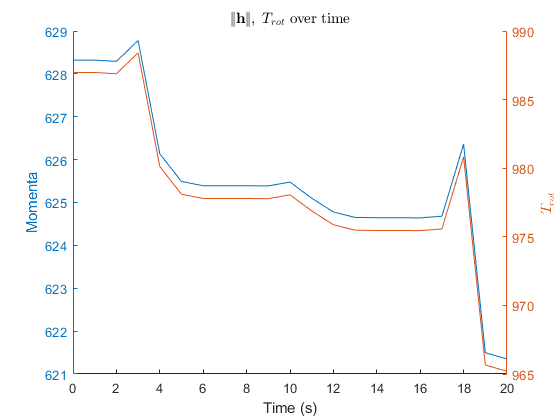

% Total Momentum and Kinetic Energy plot
figure(4)
hold on
yyaxis left
plot(tspan2,cell2mat(totMomentum2))
ylabel("Momenta")
xlabel("Time (s)");
yyaxis right
plot(tspan2, cell2mat(Trot2));
ylabel("$T_{rot}$", "Interpreter","latex")
hold off;
title("$|\!| \textbf{h} |\!|,\ T_{rot} $ over time","Interpreter","latex")

## Function

Write a matlab function to solve this ODE, given initial conditions and a timespan

Output the following:

- Angular Rates ($\omega$'s)

- momenta along each axis

- Total momentum (magnitude) and kinetic energy

Solution:

function [w, momenta_matrix, totMomentum, Trot] = AngularRateODESolver(Imat, w_init, tspan)
    % Inertia Values
    Ix = Imat(1,1);
    Iy = Imat(2,2);
    Iz = Imat(3,3);
    
    % differential equation here
    func = @(t,w) [((Iy - Iz)/Ix)*w(2)*w(3); ((Iz - Ix)/Iy)*w(1)*w(3); ((Ix - Iy)/Iz)*w(1)*w(2)];
    
    % ode45 solver
    [t,w] = ode45(func, tspan, w_init);
    
    for i = 1:length(tspan)
        momenta_matrix{:,i} = [Ix * w(i,1); Iy * w(i,2); Iz*w(i,3)];
        totMomentum{i} = norm(momenta_matrix{:,i});
        Trot{i} = 0.5*dot([w(i,1); w(i,2);w(i,3)],momenta_matrix{:,i});
    end
end